# User Days 2020 NWB Tutorial - Optical Physiology

## Introduction

In this tutorial, we will create fake data for a hypothetical optical physiology experiment with a freely moving animal. The types of data we will convert are:

- Subject (species, strain, age, etc.)

- Animal position

- Trials

- Acquired two-photon images

- Image segmentation (ROIs)

- Fluorescence and dF/F response

## Installing MatNWB

To install MatNWB, add the matnwb repo to your path, and run `generateCore()` from within the matnwb directory.

## Set up the NWB file

An NWB file represents a single session of an experiment. Each file must have a session description, identifier, and session start time. Create a new `NwbFile` object with those and additional metadata.

date = datetime(2018, 3, 1, 12, 0, 0);
session_start_time = datetime(date, 'TimeZone', 'local');

nwb = NwbFile( ...
    'session_description', 'a test NWB File', ...
    'identifier', 'mouse004_day4', ...
    'session_start_time', session_start_time);

You can check the contents by displaying the NwbFile object

disp(nwb);

## Subject

Create a `Subject` object to store information about the experimental subject, such as age, species, genotype, sex, and a freeform description. 

nwb.general_subject = types.core.Subject( ...
    'subject_id', '001', ...
    'description', 'mouse 5', ...
    'age', 'P90D', ...
    'sex', 'M', ...
    'species', 'Mus musculus');

## Behavior

### SpatialSeries

`SpatialSeries` is a subclass of `TimeSeries`. `TimeSeries` is a common base class for measurements sampled over time, and provides fields for data and time (regularly or irregularly sampled). The `Position` object holds one or more `SpatialSeries` objects. 

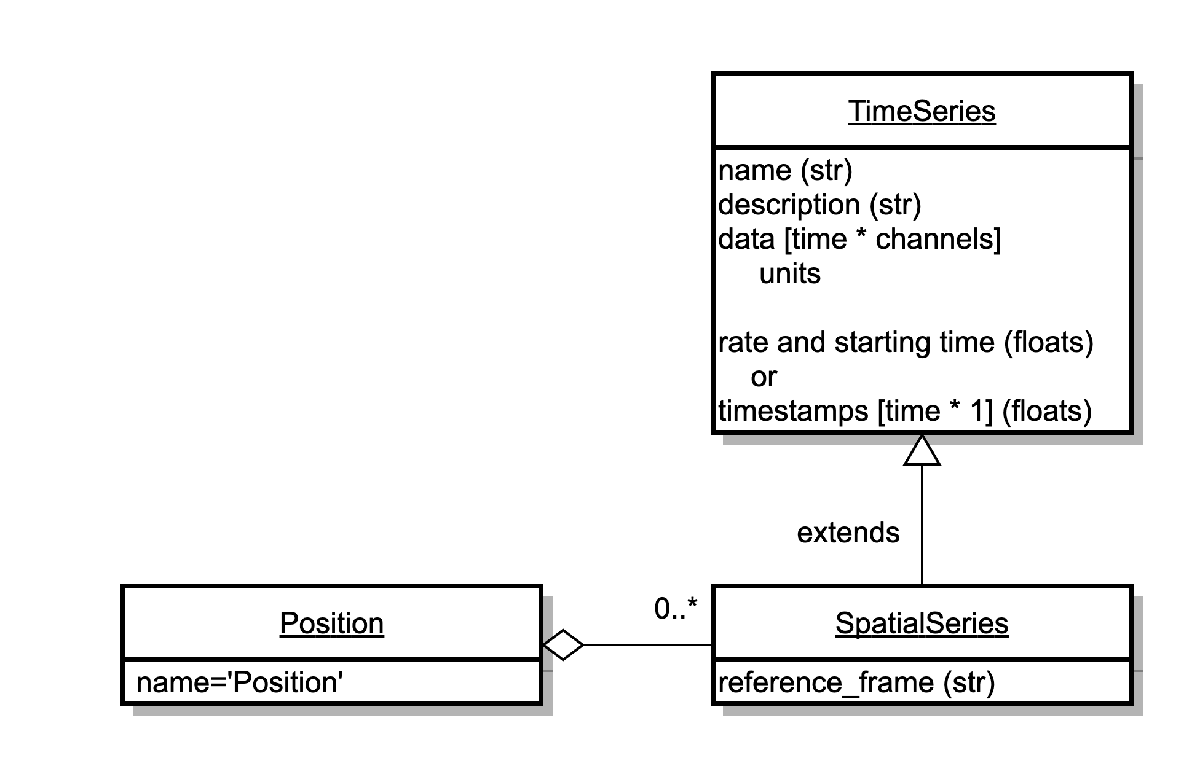

Create a `SpatialSeries` object named `'position'` with some fake data.

position_data = [linspace(0,10,100); linspace(1,8,100)]';

position_ts = types.core.SpatialSeries( ...
    'data', position_data, ...
    'reference_frame', 'unknown', ...
    'data_conversion', 1.0, ...
    'data_resolution', NaN, ...
    'timestamps', linspace(0, 100)/200)

behavior_mod = types.core.ProcessingModule( ...
    'description',  'contains behavioral data');

Position = types.core.Position('SpatialSeries', position_ts);
behavior_mod.nwbdatainterface.set(...
    'Position', Position);

nwb.processing.set('behavior', behavior_mod);

### Test write

nwbExport(nwb, 'ophys_tutorial.nwb')

### Trials

`DynamicTable` objects are used to store tabular meta-data throughout NWB, including electrodes, and sorted units. They offer flexibility for tabular data by allowing required columns, optional columns, and custom columns.

Trials are stored in a `TimeInterval` object which subclasses  DynamicTable. Here, we are adding `'correct'`, which will be a `boolean` array.

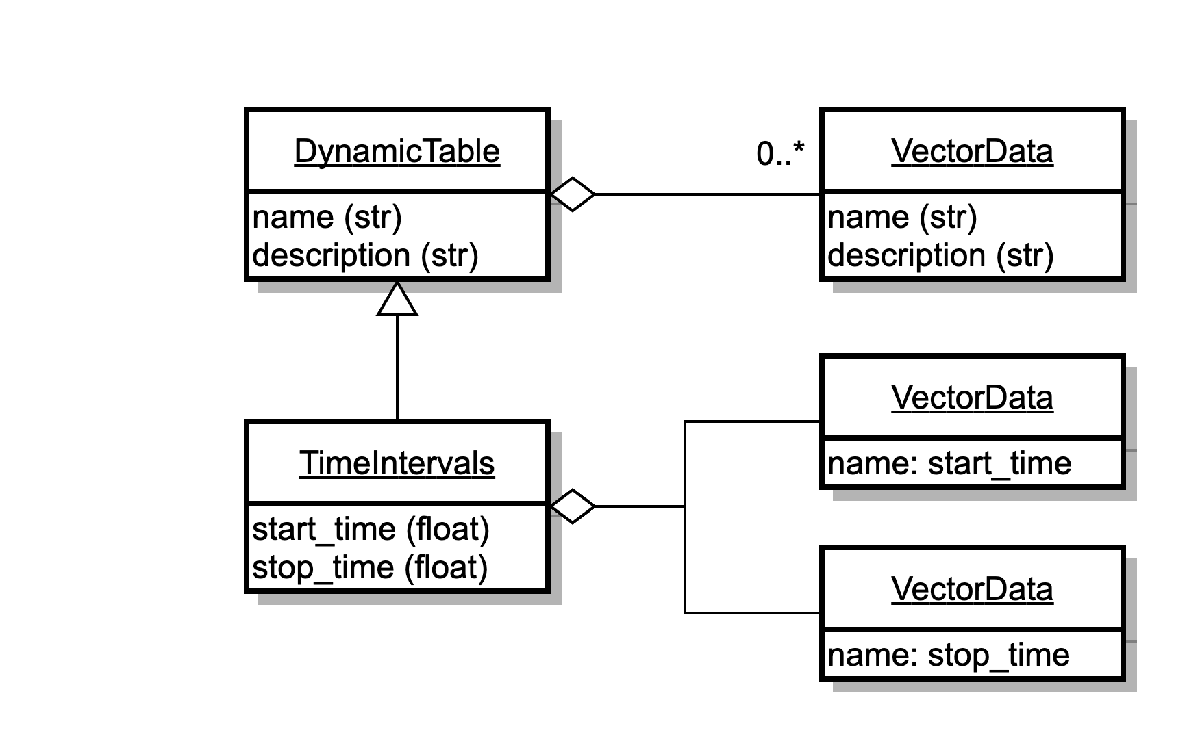

trials = types.core.TimeIntervals( ...
    'colnames', {'start_time', 'stop_time', 'correct'}, ...
    'description', 'trial data and properties', ...
    'id', types.core.ElementIdentifiers('data', 0:2), ...
    'start_time', types.core.VectorData('data', [.1, 1.5, 2.5], ...
   	'description','start time of trial'), ...
    'stop_time', types.core.VectorData('data', [1., 2., 3.], ...
   	'description','end of each trial'), ...
    'correct', types.core.VectorData('data', [false, true, false], ...
   	'description', 'my description'))
nwb.intervals_trials = trials;

## Optical Physiology

Optical physiology results are written in four steps:

- Create imaging plane

- Acquired two-photon images

- Image segmentation

- Fluorescence and dF/F responses

### Imaging Plane

First, you must create an `ImagingPlane` object, which will hold information about the area and method used to collect the optical imaging data. This requires creation of a `Device` object for the microscope and an `OpticalChannel` object. Then you can create an `ImagingPlane`.

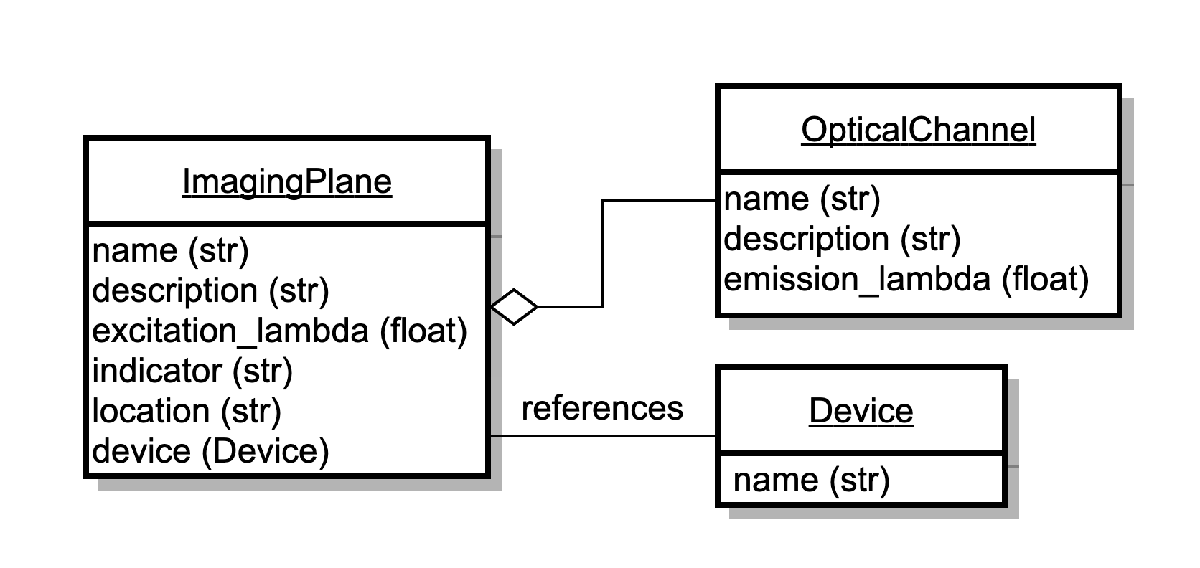

optical_channel = types.core.OpticalChannel( ...
    'description', 'description', ...
    'emission_lambda', 500.);

device_name = 'Device';
nwb.general_devices.set(device_name, types.core.Device());

imaging_plane_name = 'imaging_plane';
imaging_plane = types.core.ImagingPlane( ...
    'optical_channel', optical_channel, ...
    'description', 'a very interesting part of the brain', ...
    'device', types.untyped.SoftLink(['/general/devices/' device_name]), ...
    'excitation_lambda', 600., ...
    'imaging_rate', 5., ...
    'indicator', 'GFP', ...
    'location', 'my favorite brain location');

nwb.general_optophysiology.set(imaging_plane_name, imaging_plane);

% we are going to need this later
imaging_plane_path = ['/general/optophysiology/' imaging_plane_name];

### Storing raw optical physiology data

Now that you have your `ImagingPlane`, you can create a `TwoPhotonSeries` the class representing two photon imaging data. `TwoPhotonSeries`, like `SpatialSeries`, inherits from `TimeSeries`.

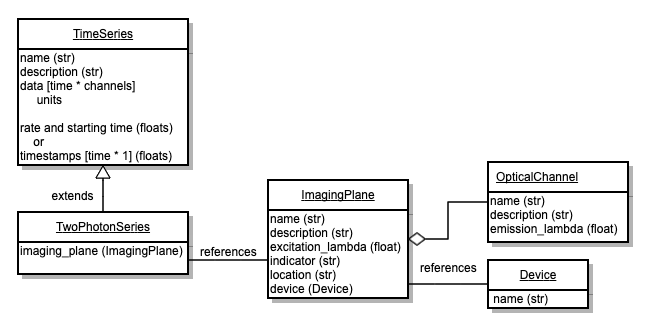

From here you have two options. The first option is to supply the image data using the `data` argument. The other option is the provide a path the images. These two options have trade-offs, so it is worth spending time considering how you want to store this data.

#### Adding the data directly to the NWBFile

image_series = types.core.TwoPhotonSeries( ...
    'imaging_plane', types.untyped.SoftLink(imaging_plane_path), ...
    'starting_time_rate', 3.0, ...
    'data', ones(200, 100, 1000), ...
    'data_unit', 'lumens');

nwb.acquisition.set('TwoPhotonSeries', image_series);

#### Linking externally to the data

image_series = types.core.TwoPhotonSeries( ...
    'external_file', 'images.tiff', ...
    'imaging_plane', types.untyped.SoftLink(imaging_plane_path), ...
    'external_file_starting_frame', 0, ...
    'format', 'tiff', ...
    'starting_time_rate', 3.0, ...
    'data', NaN, ...
    'data_unit', 'na');

nwb.acquisition.set('TwoPhotonSeries2', image_series);

### Plane Segmentation

Image segmentation stores the detected regions of interest in the `TwoPhotonSeries` data. `ImageSegmentation` allows you to have more than one segmentation by creating more `PlaneSegmentation` objects.

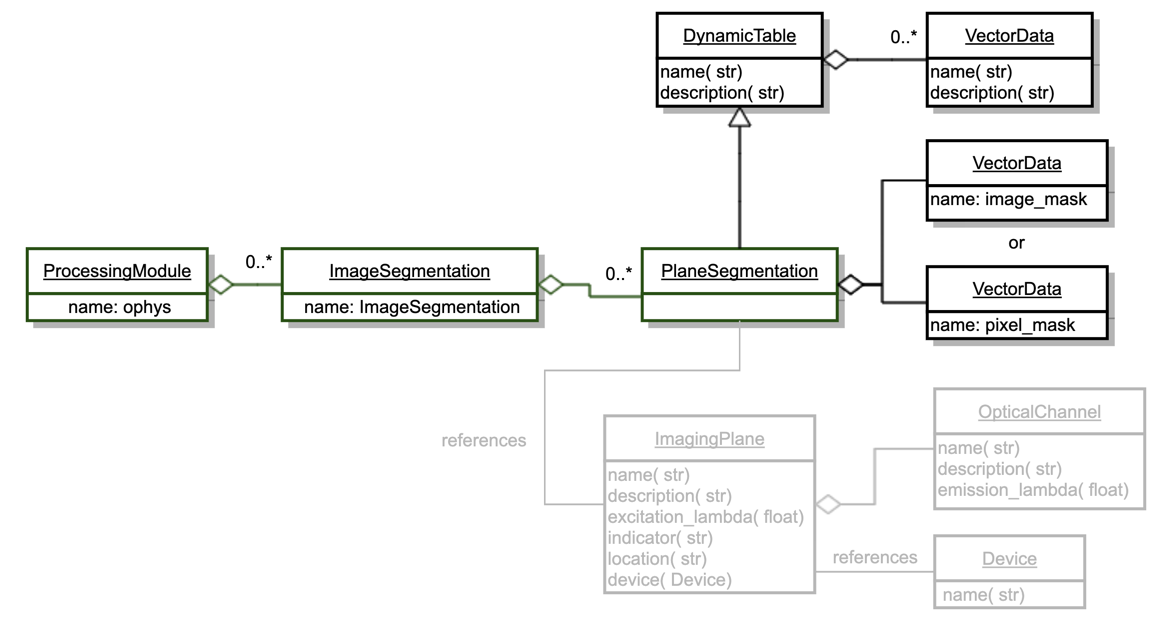

### Regions of interest (ROIs)

You may add ROIs using an image mask or using a pixel mask. An image mask is an array that is the same size as a single frame of the `TwoPhotonSeries`, and indicates where a single region of interest is. This image mask may be boolean or continuous between 0 and 1.

% generate fake image_mask data
imaging_shape = [100, 100];
x = imaging_shape(1);
y = imaging_shape(2);

n_rois = 20;
image_mask = zeros(y, x, n_rois);
for i = 1:n_rois
    start = randi(90,2,1);
    image_mask(start(1):start(1)+10, start(2):start(2)+10, 1) = 1
end

% add data to NWB structures
plane_segmentation = types.core.PlaneSegmentation( ...
    'colnames', {'imaging_mask'}, ...
    'description', 'output from segmenting my favorite imaging plane', ...
    'id', types.hdmf_common.ElementIdentifiers('data', int64(0:2)), ...
    'imaging_plane', imaging_plane);

plane_segmentation.image_mask = types.hdmf_common.VectorData( ...
    'data', image_mask, 'description', 'image masks');

img_seg = types.core.ImageSegmentation();
img_seg.planesegmentation.set('PlaneSegmentation', plane_segmentation)

ophys_module.nwbdatainterface.set('ImageSegmentation', img_seg);
nwb.processing.set('ophys', ophys_module);

### Storing fluorescence of ROIs over time

Now that ROIs are stored, you can store fluorescence dF/F data for these regions of interest. This type of data is stored using the `RoiResponseSeries` class. You will not need to instantiate this class directly to create objects of this type, but it is worth noting that this is the class you will work with after you read data back in.

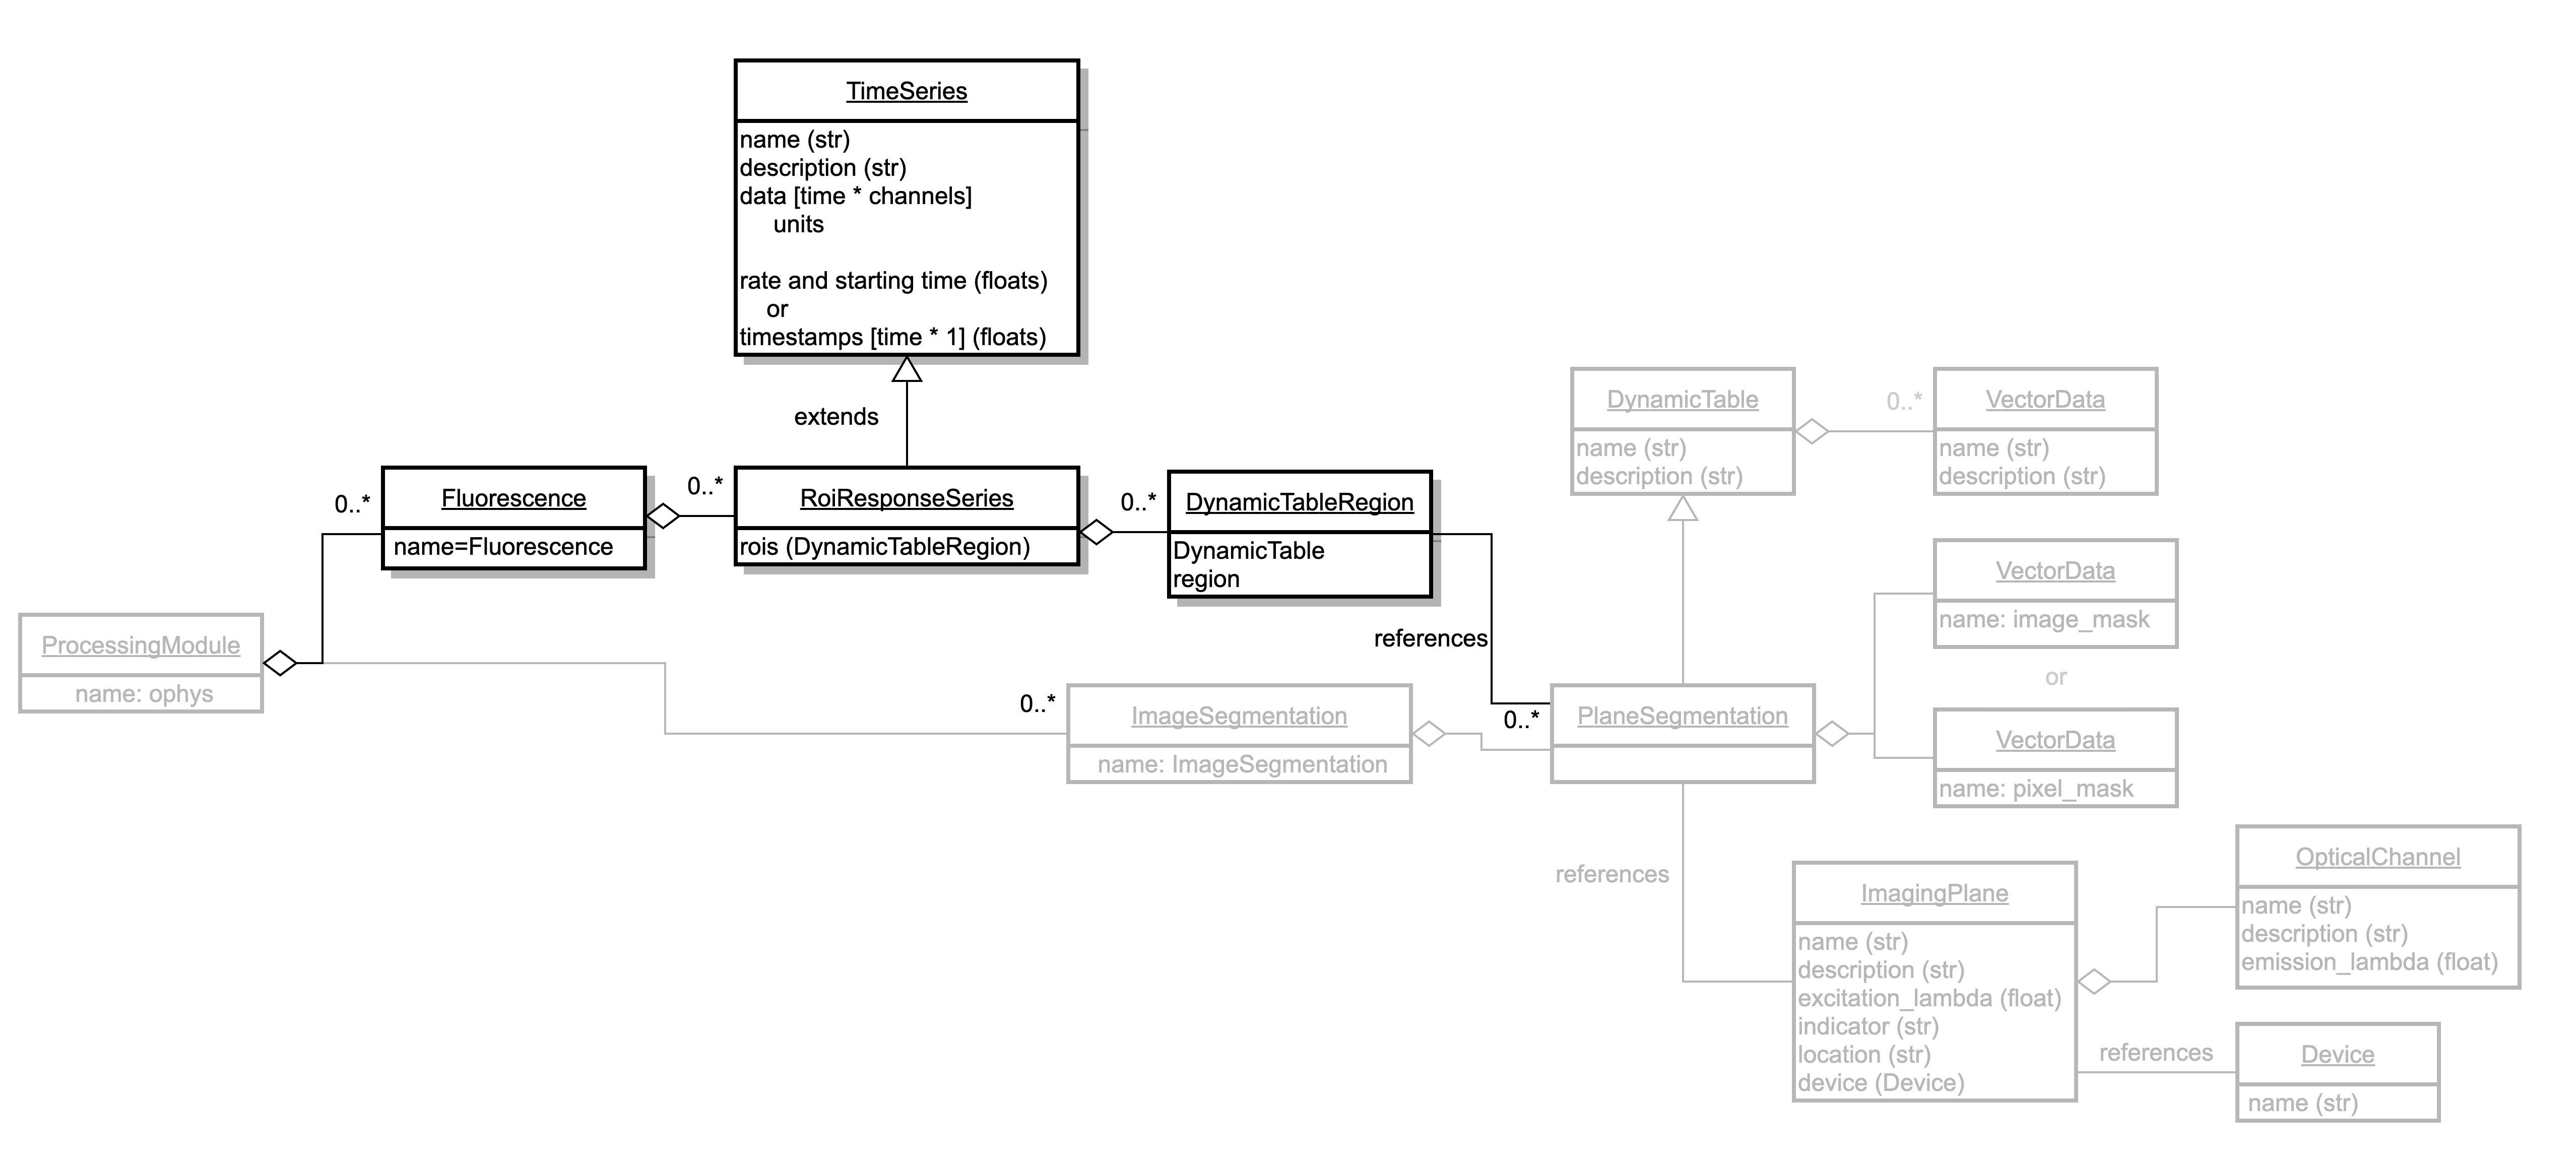

First, create a data interface to store this data in

plane_seg_object_view = types.untyped.ObjectView( ...
    '/processing/ophys/image_segmentation/PlaneSegmentation');

roi_table_region = types.hdmf_common.DynamicTableRegion( ...
    'table', plane_seg_object_view, ...
    'description', 'all_rois', ...
    'data', [0 n_rois-1]');

roi_response_series = types.core.RoiResponseSeries( ...
    'rois', roi_table_region, ...
    'data', single(NaN(n_rois, 100)), ...
    'data_unit', 'lumens', ...
    'starting_time_rate', 3.0);

fluorescence = types.core.Fluorescence();
fluorescence.roiresponseseries.set('RoiResponseSeries', roi_response_series);

ophys_module.nwbdatainterface.set('Fluorescence', fluorescence);

Finally, the ophys `ProcessingModule` is added to the `NWBFile`.

nwb.processing.set('ophys', ophys_module);

Write the NWB file

nwbExport(nwb, 'ophys_tutorial.nwb');

## Reading the NWB file

nwb = nwbRead('ophys_tutorial.nwb');

nwb.general_optophysiology.get('imaging_plane')